Problem 0: making the fake data

sample_size = 10^5;

time_axis = linspace(0, 100*pi, sample_size);
N = 10 + sin(time_axis);
background = normrnd(N, sqrt(N));
data = N + background;

## Problem 1:  subsets of data

1a) Make a scatter plot (not a line plot) of the first 1000 data points.

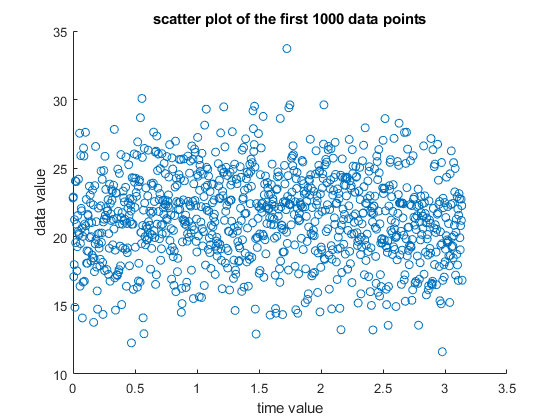

scatter_range = 1000;
figure
scatter(time_axis(1:scatter_range), data(1:scatter_range))
title(['scatter plot of the first ' num2str(scatter_range) ' data points'])
xlabel('time value')
ylabel('data value')

1b) Generalize your code so you can make a plot of any X contiguous  points (e.g. 2000 points starting at point 500), and produce an example  plot of a set of data somethere in the middle of your array.

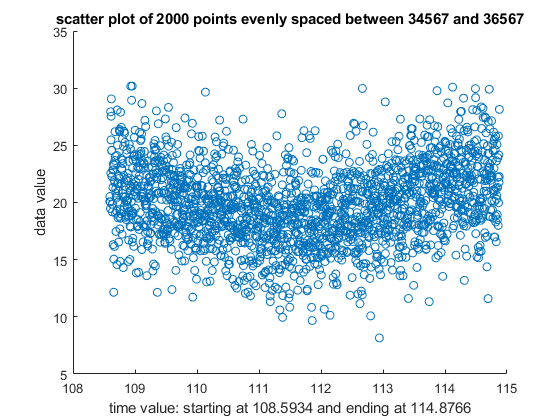

scatter_start = 34567;
scatter_step = 1;
number_of_points = 2000;
scatter_end = min(scatter_start + number_of_points*scatter_step, sample_size);
scatter_range = scatter_start:scatter_step:scatter_end;
figure
scatter(time_axis(scatter_range), data(scatter_range))
title(['scatter plot of ' num2str(number_of_points) ' points evenly spaced between ' num2str(scatter_start) ' and ' num2str(scatter_end)])
xlabel(['time value: starting at ' num2str(time_axis(scatter_start)) ' and ending at ' num2str(time_axis(scatter_end)) ])
ylabel('data value')

1c) Sometimes you want to sample the data, such as plotting every 100th point. Make a plot of the full data range, but only every 100th  point.

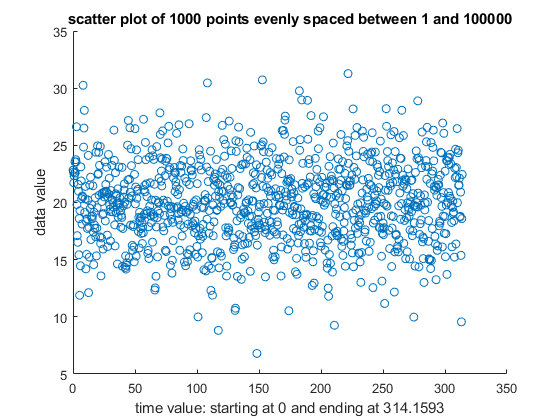

scatter_start = 1;
scatter_step = 100;
number_of_points = 1000;
scatter_end = min(scatter_start + number_of_points*scatter_step, sample_size);
scatter_range = scatter_start:scatter_step:scatter_end;
figure
scatter(time_axis(scatter_range), data(scatter_range))
title(['scatter plot of ' num2str(number_of_points) ' points evenly spaced between ' num2str(scatter_start) ' and ' num2str(scatter_end)])
xlabel(['time value: starting at ' num2str(time_axis(scatter_start)) ' and ending at ' num2str(time_axis(scatter_end)) ])
ylabel('data value')

## Problem 2: density

2a) Make a 2d histogram plot. Read about options, and play with  binsize so it is useful (too large a bin and everything washes out, too  small and the sample noise dominates). Make sure you use a colorbar.

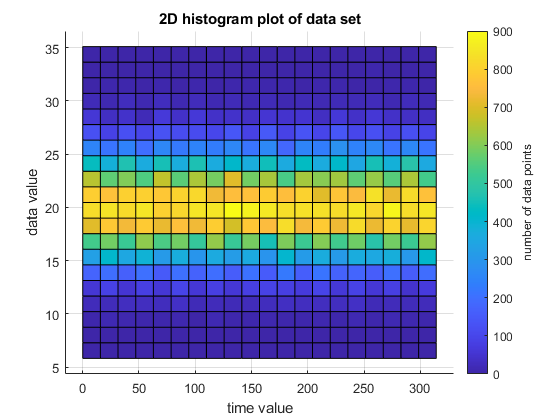

combined_data = zeros(2, sample_size);
combined_data(1, :) = time_axis;
combined_data(2, :) = data;

nbins_time = 20;
nbins_data_val = 20;

figure
hist3(combined_data', 'Nbins', [nbins_time, nbins_data_val], 'CDataMode', 'auto', "FaceColor", 'interp')
title(['2D histogram plot of data set'])
xlabel(['time value'])
ylabel(['data value'])
zlabel(['number of data points'])
c = colorbar;
ylabel(c, 'number of data points')
view(2)

2b) Clearly explain what is being plotted in your plot (e.g. what does each color mean?)

As labeled on the plot itself, the color value of each box indicates the number of data points that fall within the time value and data value ranges of that bin. Essentially, we have turned out 100,000 point data set into a 1600 point data set by dividing both the data value range and the time value range into 40 even spacings. Then in each rectangle on the 40x40 grid, we count the number of data points that fall in that range and that becomes the value graphed for that box on the above graph.

## Problem 3:  folding

Now if you have a periodic signal, it is possible to fold the data stream at that period to make the pattern clearer.

3a) Make an new time variable that folds at a period of 2*π.* Then make a scatter plot of all your data, but now folded. (Reminder,  for more data you'd never actually want to plot all the points.)

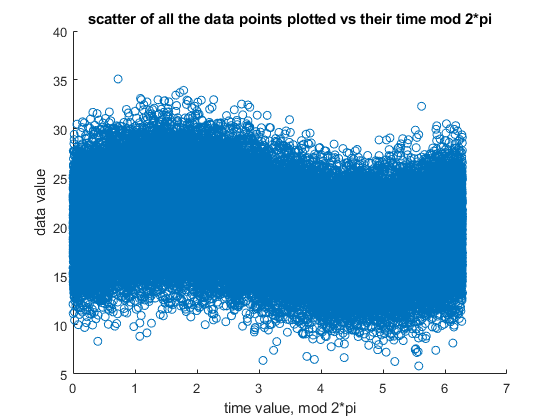

folded_time = mod(time_axis, 2*pi);

figure
scatter(folded_time, data)
title('scatter of all the data points plotted vs their time mod 2*pi')
xlabel('time value, mod 2*pi')
ylabel('data value')

3b) Make a 2D histogram plot of your folded data.

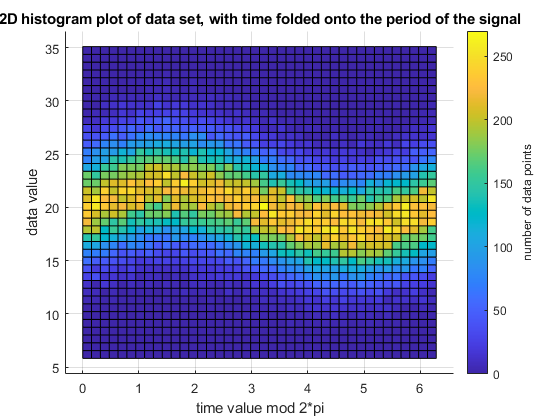

combined_data = zeros(2, sample_size);
combined_data(1, :) = folded_time;
combined_data(2, :) = data;

nbins_time = 40;
nbins_data_val = 40;

figure
hist3(combined_data', 'Nbins', [nbins_time, nbins_data_val], 'CDataMode', 'auto', "FaceColor", 'interp')
title(['2D histogram plot of data set, with time folded onto the period of the signal'])
xlabel(['time value mod 2*pi'])
ylabel(['data value'])
zlabel(['number of data points'])
c = colorbar;
ylabel(c, 'number of data points')
view(2)

3c) You can use 2D histograms or digitize functions, plus some math, to calculate the *average* as a function of the folded variable. You can then overplot this on 3b to show the average as a function of folded time.

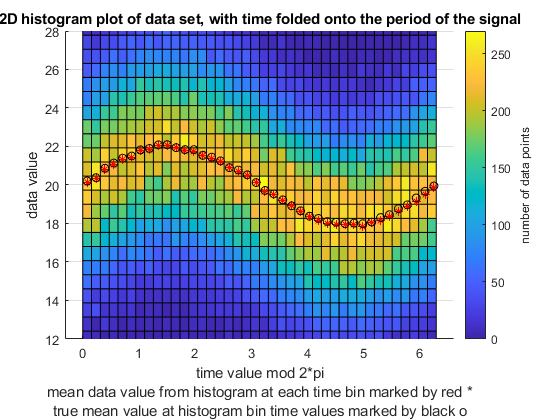

time_folded_hist_data = hist3(combined_data', 'Nbins', [nbins_time, nbins_data_val]);
[counts, time_edges, data_edges] = histcounts2(folded_time, data, 'Numbins', [nbins_time, nbins_data_val]);
central_time_values = time_edges + (time_edges(2) - time_edges(1))/2;
central_time_values = central_time_values(1:end-1);

central_data_values = data_edges + (data_edges(2) - data_edges(1))/2;
central_data_values = central_data_values(1:end-1);

[data_value_grid, time_value_grid] = meshgrid(central_data_values, central_time_values);

summed_at_fixed_time = sum(time_folded_hist_data,2);

value_weighted_hist = time_folded_hist_data .* data_value_grid;

hist_average_value = sum(value_weighted_hist,2) ./ sum(time_folded_hist_data,2);

zvals = 1.5*max(time_folded_hist_data(:))*ones(size(hist_average_value));

true_means = zeros(size(hist_average_value));

for i = 1:length(true_means)
    front_edge_or_longer = time_edges(i) <= folded_time;
    back_edge_or_shorter = time_edges(i+1) > folded_time;
    in_range = front_edge_or_longer & back_edge_or_shorter;
    indexes = find(in_range);
    data_vals_in_range = data(indexes);
    true_means(i) = mean(data_vals_in_range(:));
    
end

figure
hist3(combined_data', 'Nbins', [nbins_time, nbins_data_val], 'CDataMode', 'auto', "FaceColor", 'interp')
hold on
title(['2D histogram plot of data set, with time folded onto the period of the signal'])
xlabel({'time value mod 2*pi'; 'mean data value from histogram at each time bin marked by red *'; 'true mean value at histogram bin time values marked by black o'})
ylabel(['data value'])
zlabel(['number of data points'])
c = colorbar;
ylabel(c, 'number of data points')
line(central_time_values, hist_average_value, zvals, 'Color', 'r', 'LineStyle', 'none', 'Marker', '*')
hold on
line(central_time_values, true_means, zvals, 'Color', 'k', 'LineStyle', 'none', 'Marker', 'o')
ylim_min = 12;
ylim_max = 28;
ylim([ylim_min, ylim_max])
view(2)

I have plotted both the mean at each point as calculated from the histogram (weighting the value at the center of the histogram bin by the number of points in that bin and calculating the average value at each time) and the true mean (finding all of the data values that were taken between the time edges of each histogram bin and finding the average over all those data values) and overplotted both of them. The two mean values are different because the red means are calculated after binning the data values.   I have reduced the range of data values being displayed, because while it does't plot all of the data, it makes it easier to see the difference between the true mean and the mean calculated from the histogram data. The number of points not plotted is calculated below. 

less_than_min = data < ylim_min;
more_than_max = data > ylim_max;
excluded = less_than_min | more_than_max;
excluded_indexes = find(excluded);

disp(['the number of excluded data points is ' num2str(length(excluded_indexes))])

the number of excluded data points is 2069
